# My datastore

clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data', 'raw');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");
raw_images = readall(imds);

### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    label = imds.Files{i}(length(folder_name) + 6);
    imds.Labels{i} = label;
end


### Display raw images

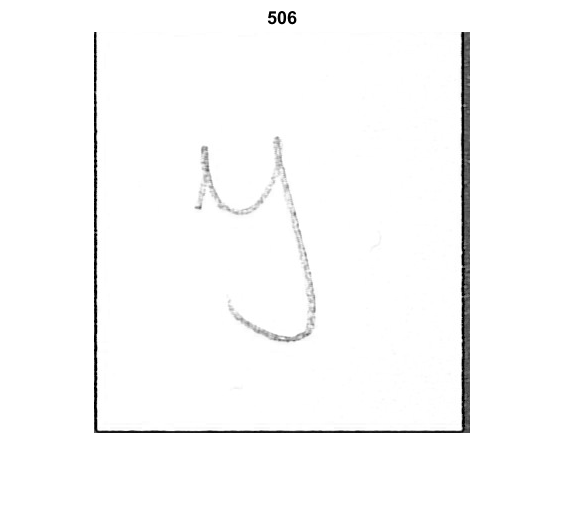

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(raw_images{rand_int})
    title(rand_int)
end

## Preprocessing images

bin_threshold = 0.9;
target_size = [400, 400];
final_size = [64, 64];
sigma = 0.5;
medfilt_size = [5, 5];

gauss_flg = true;
median_flg = true;

preprocessed_imds = transform(imds, @(x) imresize(x, target_size));

if gauss_flg
    preprocessed_imds = transform(preprocessed_imds, @(x) imgaussfilt(x, sigma));
end

preprocessed_imds = transform(preprocessed_imds, @(x) binarization(x, bin_threshold));

if median_flg
    preprocessed_imds = transform(preprocessed_imds, @(x) medfilt2(x, medfilt_size));
end
preprocessed_imds = transform(preprocessed_imds, @edge_removal);

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));



preprocessed_images = my_readall(preprocessed_imds, N);

### Display preprocessed images

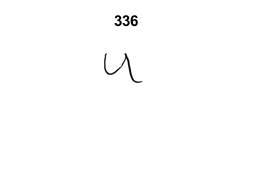

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(preprocessed_images{rand_int})
    title(rand_int)
end

## Feature extraction

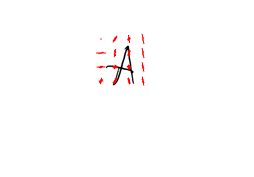

I = preprocessed_images{1};
figure('Position', [10 10 900 600]);
imshow(I);
hold on

% hog surf and kaze are good for classification apparently
% https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html

method_name = "hog";

num_points = 10;
cell_size = [14, 14];


if method_name == "hog"
    [featureVector, visualization] = extractHOGFeatures(I,'CellSize',cell_size);
    plot(visualization, 'Color','red')
elseif method_name == "surf"
    points = detectSURFFeatures(I).selectStrongest(num_points);
    [features, valid_points] = extractFeatures(I, points);
    plot(valid_points);
elseif method_name == "kaze"
    points = detectKAZEFeatures(I).selectStrongest(num_points);
    [features, valid_points] = extractFeatures(I, points);
    plot(valid_points);
end

hold off
if method_name == "hog"
    data = zeros(N, length(featureVector), 'double');
    for i = 1:N
        [feature_vector, ~] = extractHOGFeatures(preprocessed_images{i},'CellSize',cell_size);
        data(i, :) = feature_vector;
    end
end

### Dimensionality reduction

[coeff,~,~,~,explained,~] = pca(data);
explained

explained =    17.7778
    9.6642
    9.1277
    6.4595
    6.0256
    4.5683
    3.7871
    2.6487
    2.4298
    2.2857


feature_vector_size = 70;
sum(explained(1:feature_vector_size))

ans = 93.9675

A_dim_reduction = coeff(:, 1:feature_vector_size);
data_low_dim = data * A_dim_reduction;

## Dividing the dataset

training.labels = {};
training.data = [];

testing.labels = {};
testing.data = [];

for i = 1:N
    if rand < 0.7
        training.labels{end + 1} = imds.Labels{i};
        training.data = [training.data; data_low_dim(i, :)];
    else
        testing.labels{end + 1} = imds.Labels{i};
        testing.data = [testing.data; data_low_dim(i, :)];
    end
end

## Finding the probability density functions

training_classes = distribution_parameters(imds, training)

training_classes = struct with fields:
    labels: {5×1 cell}
      data: {5×1 cell}
     sigma: {5×1 cell}
         M: {5×1 cell}
         P: {5×1 cell}


dets = det(training_classes.sigma{1})

dets = 8.9610e-160

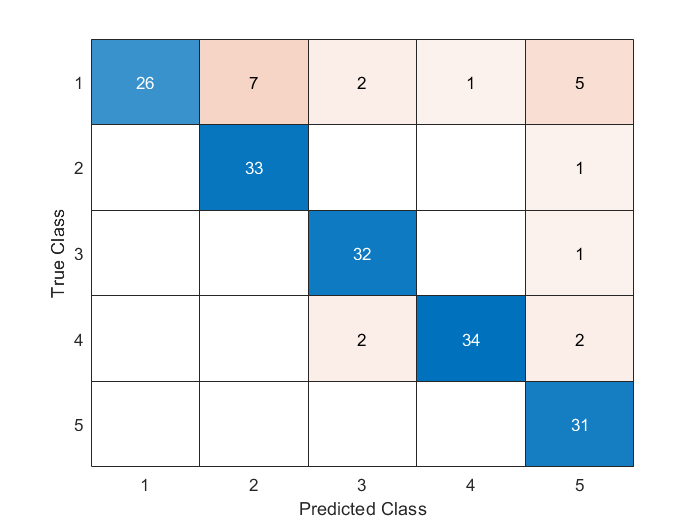

% test_result = zeros(length(testing.labels), 1);
test_result = cell(length(testing.labels), 1);
for i = 1:length(testing.labels)
   test_result{i} = char(bayes_test_least_error(testing.data(i, :), training_classes));
end

C = confusionmat(test_result, testing.labels);

figure()
confusionchart(C)

## Dividing the datastore

`[trainingSet, validationSet] = splitEachLabel(imds, 0.6, ``'randomize'``); ?`

### Shuffling the datastore

% preprocessed_imds = shuffle(preprocessed_imds);
% preprocessed_images = my_readall(preprocessed_imds, N);
% preprocessed_imds.UnderlyingDatastore.Labels{1:5}

### Dividing the datastore into training and testing

% partition_index = round(N * 0.7);
% 
% training_imds = subset(preprocessed_imds, 1:partition_index);
% testing_imds = subset(preprocessed_imds, partition_index + 1 :N);